## fv6 Intro

In this scrip, i adapt the fv5 and no longer needs to adjust the experiment number N according to the residual. For example, if gradient (in one direction) is about 1e-25m^4, we should let the error less than 1e-26m^4.

Making test by scrip 'parameter_selecting_error_estimation', we got data. Now i suppose we need 1000 simulation to get error approx to 1e10nm^4.

We uses 4 parameters: m, zeta, psi and H. 

## fv7 Intro

In this scrip, i adapt the fv6, add a part to get the relationship between Error and N, so that there is no need to import it by hand.

Also we save this relationship. Adittionally N will be printed in step so that i can know how long one step will take.

But actually, I wonder whether this part is necessary, for maybe parameter change a little, error_N_relationship change a lot.

## fv10 Intro

In this scrip, i adapt input part to use fitness cuurve as experiment data.

## Import data and previewing

cut down the declining part, we delete all data after the maximum one.

experiment_interval=5

experiment_interval = 5

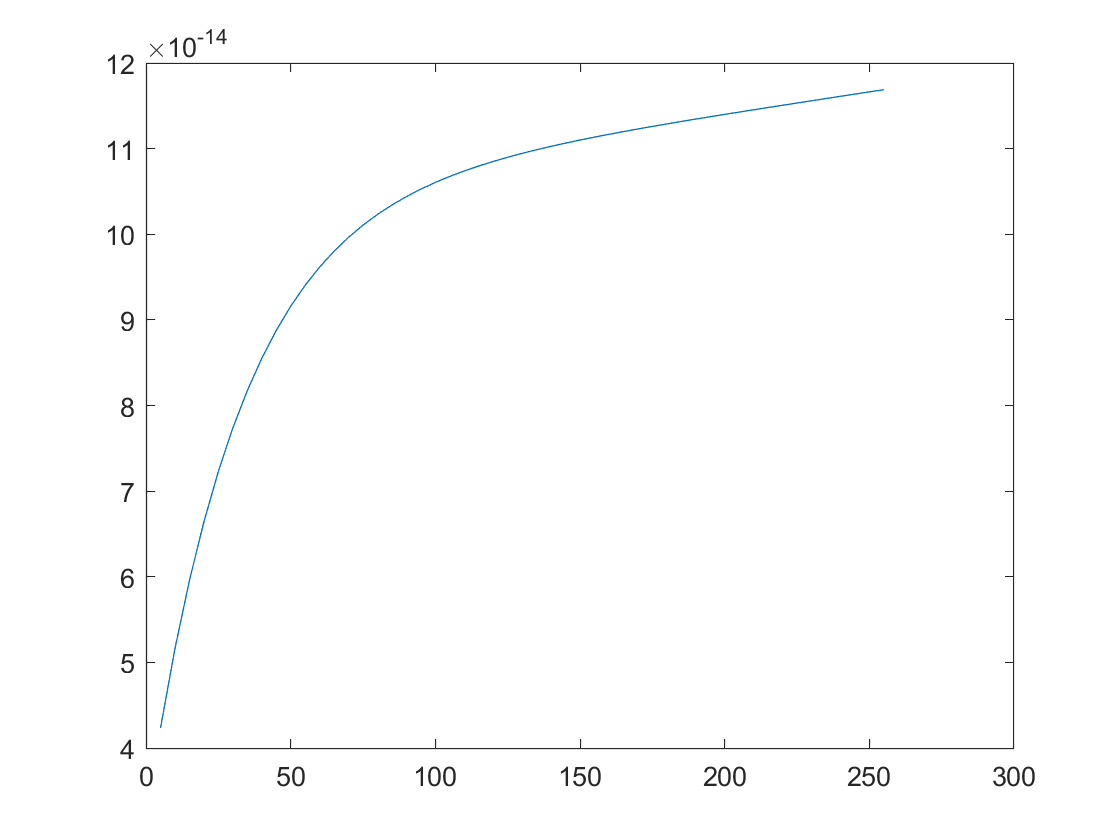

min_length=51;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.046e+05;
a(2)=0.0004364;
a(3)=-7.307e+04;
a(4)=-0.03125;

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);
plot(time_scale,interceptive_experiment_MSD)

## Data Importing

import time settings

% import Time interval
delta=0.1;

Initilizing parameters

% input the initial parameter

input=[6e-09,0.5,2e-08,0.75];
m_0=input(1);
psi_0=input(2);
zeta_0=input(3);
H_0=input(4);

% put it in use

m=m_0

m = 6.0000e-09

psi=psi_0

psi = 0.5000

zeta=zeta_0

zeta = 2.0000e-08

H=H_0

H = 0.7500


% decide step length and sample length (proportional)

step_length=1/50;
sample_length=1/50;

%setting stopping condition
residual_limit=1e-25;

## storage system

% add parameter history and gradient history
parameter_history=[m,psi,zeta,H];
gradient_history=[];
residual_history=[];
N_history=[];

## Main loop

%% Calculating decline in three direction
% 
step_number=0;
Total_experiment_number=100;%initializtion
while step_number<=5
    step_number=step_number+1
    disp(['------step',num2str(step_number),' N= ',num2str(Total_experiment_number),'--------'])
    residual_0=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H,m,delta,Total_experiment_number);
    residual_m=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H,m*(1+sample_length),delta,Total_experiment_number);
    residual_psi=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi*(1+sample_length),zeta,H,m,delta,Total_experiment_number);
    residual_zeta=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta*(1+sample_length),H,m,delta,Total_experiment_number);
    residual_H=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H*(1+sample_length),m,delta,Total_experiment_number);
    gradient=[residual_m-residual_0,residual_psi-residual_0,residual_zeta-residual_0,residual_H-residual_0]/sample_length;
    delta_min=min(gradient)*sample_length;
    unit_gradient=gradient/norm(gradient);
    if step_number==1
        standard_gradient=norm(gradient);
    end
%% 
% make new parameter in the opposute direction of gradient
    por=norm(gradient)/standard_gradient;
    m=m*(1-unit_gradient(1)*step_length*por)
    psi=psi*(1-unit_gradient(2)*step_length*por)
    zeta=zeta*(1-unit_gradient(3)*step_length*por)
    H=H*(1-unit_gradient(4)*step_length*por)
    parameter_history=[parameter_history;[m,psi,zeta,H]];
    gradient_history=[gradient_history;gradient];
    residual_history=[residual_history;[residual_0,Total_experiment_number]];
    disp(['residual = ',num2str(residual_0),', N = ',num2str(Total_experiment_number)])
    %end or not?
    if residual_0<=residual_limit
        break
    end
    
    %changing N
end

step_number = 1

------step1 N= 100--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 5.9928e-09

psi = 0.4995

zeta = 1.9982e-08

H = 0.7494

residual = 1.6167e-25  1.1415e-25  8.0332e-26   5.643e-26  3.9691e-26   2.811e-26  2.0232e-26  1.4999e-26  1.1645e-26  9.6174e-27   8.517e-27  8.0575e-27  8.0341e-27  8.3012e-27   8.756e-27  9.3264e-27  9.9628e-27  1.0631e-26  1.1309e-26  1.1982e-26  1.2641e-26   1.328e-26  1.3899e-26  1.4496e-26  1.5071e-26  1.5627e-26  1.6164e-26  1.6686e-26  1.7193e-26  1.7689e-26  1.8175e-26  1.8652e-26  1.9124e-26   1.959e-26  2.0053e-26  2.0514e-26  2.0974e-26  2.1434e-26  2.1895e-26  2.2358e-26  2.2823e-26  2.3292e-26  2.3764e-26   2.424e-26  2.4721e-26  2.5208e-26  2.5699e-26  2.6197e-26    2.67e-26   2.721e-26  2.7726e-26, N = 100


step_number = 2

------step2 N= 100--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 5.9870e-09

psi = 0.4991

zeta = 1.9967e-08

H = 0.7489

residual = 1.5409e-25  1.0845e-25   7.625e-26  5.3739e-26  3.8196e-26  2.7646e-26  2.0656e-26  1.6189e-26  1.3498e-26  1.2044e-26  1.1441e-26  1.1414e-26  1.1768e-26  1.2365e-26  1.3108e-26  1.3933e-26  1.4793e-26  1.5661e-26  1.6516e-26  1.7347e-26  1.8149e-26  1.8918e-26  1.9654e-26  2.0359e-26  2.1034e-26  2.1682e-26  2.2305e-26  2.2908e-26  2.3492e-26   2.406e-26  2.4615e-26  2.5159e-26  2.5695e-26  2.6224e-26  2.6747e-26  2.7267e-26  2.7785e-26  2.8302e-26  2.8819e-26  2.9337e-26  2.9857e-26   3.038e-26  3.0906e-26  3.1436e-26  3.1971e-26   3.251e-26  3.3055e-26  3.3605e-26  3.4162e-26  3.4724e-26  3.5293e-26, N = 100


step_number = 3

------step3 N= 100--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 6.0128e-09

psi = 0.5009

zeta = 2.0030e-08

H = 0.7509

residual = 2.1618e-25  1.6096e-25  1.2053e-25  9.0943e-26  6.9314e-26  5.3523e-26  4.2015e-26  3.3649e-26  2.7588e-26  2.3215e-26  2.0081e-26  1.7854e-26  1.6289e-26   1.521e-26  1.4484e-26  1.4016e-26  1.3736e-26  1.3591e-26  1.3544e-26  1.3568e-26  1.3643e-26  1.3754e-26  1.3892e-26  1.4047e-26  1.4217e-26  1.4395e-26  1.4581e-26  1.4772e-26  1.4967e-26  1.5167e-26  1.5369e-26  1.5574e-26  1.5783e-26  1.5995e-26   1.621e-26  1.6429e-26  1.6652e-26   1.688e-26  1.7111e-26  1.7348e-26  1.7589e-26  1.7835e-26  1.8087e-26  1.8345e-26  1.8608e-26  1.8877e-26  1.9152e-26  1.9434e-26  1.9722e-26  2.0016e-26  2.0318e-26, N = 100


step_number = 4

------step4 N= 100--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 6.0401e-09

psi = 0.5028

zeta = 2.0094e-08

H = 0.7529

residual = 1.7659e-25  1.2774e-25  9.2789e-26  6.7911e-26  5.0332e-26  3.8029e-26  2.9528e-26  2.3757e-26  1.9938e-26  1.7508e-26  1.6059e-26  1.5296e-26  1.5008e-26  1.5044e-26  1.5296e-26  1.5688e-26  1.6167e-26  1.6696e-26  1.7249e-26  1.7811e-26  1.8369e-26  1.8918e-26  1.9454e-26  1.9975e-26  2.0481e-26  2.0972e-26  2.1449e-26  2.1914e-26  2.2368e-26  2.2813e-26   2.325e-26  2.3681e-26  2.4107e-26  2.4529e-26   2.495e-26  2.5369e-26  2.5789e-26  2.6209e-26   2.663e-26  2.7054e-26  2.7481e-26  2.7911e-26  2.8346e-26  2.8785e-26  2.9229e-26  2.9678e-26  3.0132e-26  3.0592e-26  3.1059e-26  3.1532e-26  3.2011e-26, N = 100


step_number = 5

------step5 N= 100--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 6.0237e-09

psi = 0.5017

zeta = 2.0058e-08

H = 0.7519

residual = 1.1974e-25   7.993e-26  5.2736e-26  3.4529e-26   2.269e-26  1.5329e-26  1.1088e-26  8.9941e-27  8.3539e-27  8.6756e-27  9.6133e-27  1.0926e-26  1.2446e-26  1.4063e-26    1.57e-26  1.7311e-26  1.8867e-26   2.035e-26  2.1754e-26  2.3077e-26   2.432e-26   2.549e-26  2.6591e-26  2.7629e-26  2.8612e-26  2.9545e-26  3.0435e-26  3.1288e-26  3.2108e-26  3.2901e-26  3.3671e-26  3.4421e-26  3.5156e-26  3.5877e-26  3.6588e-26  3.7292e-26  3.7989e-26  3.8682e-26  3.9373e-26  4.0063e-26  4.0752e-26  4.1443e-26  4.2136e-26  4.2832e-26  4.3532e-26  4.4236e-26  4.4944e-26  4.5658e-26  4.6378e-26  4.7103e-26  4.7835e-26, N = 100


step_number = 6

------step6 N= 100--------


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


m = 6.0244e-09

psi = 0.5017

zeta = 2.0060e-08

H = 0.7519

residual = 1.4713e-25  1.0222e-25  7.0639e-26  4.8663e-26  3.3581e-26  2.3428e-26   1.678e-26  1.2609e-26  1.0173e-26  8.9398e-27  8.5288e-27  8.6686e-27  9.1675e-27   9.891e-27  1.0746e-26  1.1668e-26  1.2616e-26   1.356e-26  1.4483e-26  1.5376e-26  1.6232e-26  1.7051e-26  1.7833e-26  1.8579e-26  1.9292e-26  1.9976e-26  2.0632e-26  2.1266e-26  2.1879e-26  2.2476e-26  2.3057e-26  2.3627e-26  2.4188e-26   2.474e-26  2.5287e-26   2.583e-26   2.637e-26  2.6909e-26  2.7448e-26  2.7987e-26  2.8529e-26  2.9072e-26  2.9619e-26   3.017e-26  3.0725e-26  3.1285e-26   3.185e-26  3.2421e-26  3.2997e-26   3.358e-26  3.4169e-26, N = 100


## saving

saving data

saving_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.02图像';
save([saving_location,'\data\history data N=',num2str(Total_experiment_number),' step=',num2str(step_length),datestr(now,' yyyy-mm-dd HH'),'.mat'],'parameter_history','gradient_history','residual_history')

Plot and plot saving: gradient history

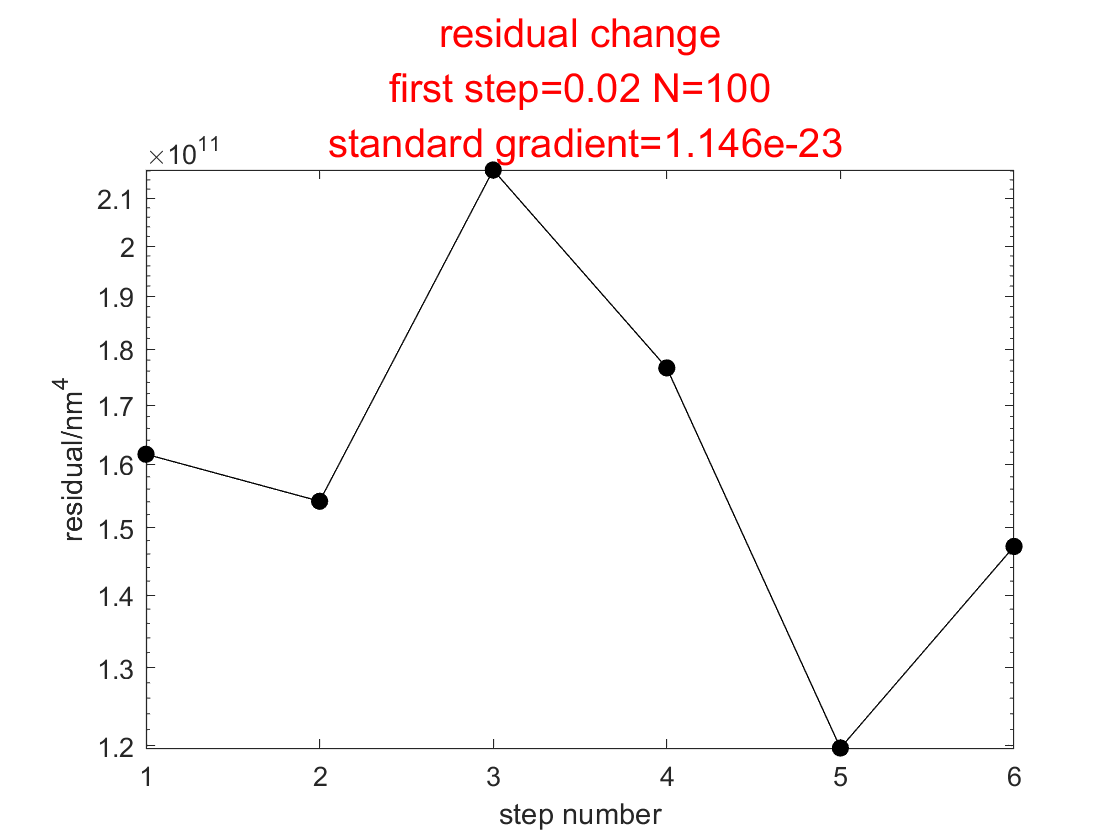

figure
plot((residual_history(:,1))*1e36,'k-o','MarkerFaceColor','k')
xlabel('step number')
ylabel('residual/nm^4')
set(gca,'yscale','log');
title({'residual change',['first step=',num2str(step_length),' N=',num2str(Total_experiment_number)],[' standard gradient=',num2str(standard_gradient)]},'Color','r','FontSize',15)

% saving
saveas(gcf,[saving_location,'\image\residual history image N=',num2str(Total_experiment_number),' step=',num2str(step_length),' ',datestr(now,'yyyy-mm-dd HH'),'.png'])